# TFM SCRIPT 3

## Aeroelastic equations in State Space formulation

Until now, the equations of the aeroelastic system have been formulated in the frequency domain. In this section, it is intended to develop a new formulation of the studied system, but writing down the equations in the time domain, more specifically in a state space representation. In order to do so, it is important to take into account the augment aerodynamic states developed in the previous section. This will allow to write down the unsteady aerodynamic forces as ordinary differential equations, avoiding having to deal with the integro-differential equations that result from the direct application of the Duhamel's convolution integral from Wagner's theory.

When dealing with state space representations, it is common to use the notation $\dot x = Ax+Bu$, where $x$ and $u $ are the states and control vectors respectively, and $A $and $B$ are the state and the input matrices. For this case, there is not control. Thus, the system is reduced to the form $\dot x = Ax$.

The first system to be considered is the 2 degrees of freedom classical airfoil, being this 2 DoF's the plunge $h$ and the pitch $\alpha$. Hence, the vector of states is:


$$\left\{\frac{h}{b}, \alpha , \frac{\dot h}{b}, \dot \alpha, x_1^{aero}, x_2^{aero}\right\}^T = \left\{x_1, x_2, x_3, x_4, x_5, x_6\right\} ^T$$


Being $x_1^{aero} = x_5$ and $x_2^{aero} = x_6$ the two aerodynamic lag states explained in the previous section. Note that there are two new lag sates due to the fact that the Jones approximation to the Wagner's indicial function contains two exponential terms. In case, a different approximation of the Wagner's function is used, the number of these aerodynamic lag states could change. Nevertheless, the equations are exactly the same for each of this states, thus, the procedure can be generalized easily.

The next step is to write down the 6 ordinary differential equations that will completely define the state matrix $A$. Starting with the first two, which relate the airfoil degrees of freedom with its respective derivatives:


$$\dot x_1 = x_3$$



$$\dot x_2 = x_4$$


In matrix form for the state-space representation:


$$\left\{ \matrix{ \dot x_1 \cr \dot x_2 } \right\} =  \left[\matrix{0 & 0 \cr  0 & 0}\right] \left\{ \matrix{x_1 \cr  x_2 } \right\}  + \left[\matrix{1 & 0 \cr  0 & 1}\right] \left\{ \matrix{x_3 \cr  x_4 } \right\} + \left[\matrix{0 & 0 \cr  0 & 0}\right] \left\{ \matrix{x_5 \cr  x_6 } \right\}$$


The next two equations relate the motion of the airfoil with the unsteady aerodynamic forces. They are the two equations applied originally in the Theodorsen's flutter theory. Firstly, the unsteady lift and moment, particularized to the case of having 2 aerodynamic lag states is:


$$C_l(\tau) = 2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right) + 4 \pi \left[\hat w_{3/4}(\tau) \Phi_0+ \epsilon_1 \psi_1 x_1(\tau) + \epsilon_2 \psi_2 x_2(\tau) \right]$$



$$C_m(\tau) = -2\pi\left[\left(\frac{1}{2}-a\right)\dot{\alpha} + a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right] + 4 \pi\left(\frac{1}{2}+a\right) \left[\hat w_{3/4}(\tau) \Phi_0+ \epsilon_1 \psi_1 x_1(\tau) + \epsilon_2 \psi_2 x_2(\tau)  \right]$$


where $\hat w_{3/4} = \alpha + \frac{\dot h}{b} +  \left(\frac{1}{2} -a\right)\dot \alpha$ and $\Phi_0 = \Phi(\tau = 0) = 1 -\psi_1-\psi_2$.

Applying the new notation for the state space representation, these last equations for the aerodynamic loads become:


$$C_l(\tau) = 2\pi \left(\dot x_3+x_4-a\dot x_4\right) + 4\pi\left[\Phi_0\left(x_2+x_3+\left(\frac{1}{2}-a\right)x_4\right) +\epsilon_1 \psi_1 x_5 + \epsilon_2 \psi_2 x_6\right]$$



$$C_m(\tau) = -2\pi \left[-a\dot x_3 + \left(\frac{1}{2}-a\right)x_4 + \left(\frac{1}{8} + a^2\right)\dot x_4 \right] + 4\pi\left(\frac{1}{2}+a\right) \left[\Phi_0\left(x_2+x_3+\left(\frac{1}{2}-a\right)x_4\right)+ \epsilon_1 \psi_1 x_5 + \epsilon_2 \psi_2 x_6 \right]$$


Note the derivatives are coupled and thus, the equations need to be modified to get each derivative decoupled. First of all, the structural terms need to be included in order to define the complete equations. The clever way to do this is by making use of matrices, as it allows to reorganize each contribution better, and is going to be the more direct way to uncouple the system of two equations: 


$$\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right]\left\{\matrix{ \dot x_3 \cr \dot x_4}\right\}  + k_\alpha^2 \left[\matrix{\left(\frac{\omega_h}{\omega_\alpha}\right)^2 & 0 \cr  0 & r_\alpha^2}\right] \left\{\matrix{ x_1 \cr x_2}\right\}  = -\frac{1}{\mu}\left[\matrix{1 & -a \cr  -a & \left( \frac{1}{8}+a^2 \right)}\right]\left\{\matrix{ \dot x_3 \cr \dot x_4}\right\}  -\frac{1}{\mu} \left[\matrix{0 & 1 \cr  0 & \left(\frac{1}{2}-a\right)}\right]\left\{\matrix{ x_3 \cr  x_4}\right\} - \frac{2\Phi_0}{\mu} \left[\matrix{1 & \left( \frac{1}{2} - a\right) \cr -\left(\frac{1}{2}+a\right) & -\left(\frac{1}{4} - a^2\right)}\right]\left\{\matrix{ x_3 \cr  x_4}\right\} -\frac{2\Phi_0}{\mu} \left[\matrix{0 & 1 \cr  0 & -\left(\frac{1}{2}+a\right)}\right]\left\{\matrix{ x_1 \cr  x_2}\right\} - \frac{2}{\mu} \left[\matrix{\epsilon_1\psi_1 & \epsilon_2\psi_2  \cr  -\epsilon_1\psi_1\left(\frac{1}{2} +a\right)  & -\epsilon_2\psi_2\left(\frac{1}{2} +a\right) }\right]\left\{\matrix{ x_5 \cr  x_6}\right\}$$


Where $k_\alpha = \frac{\omega_\alpha b}{U_\infty}$ is the natural reduced frequency of the torsion mode, and $\mu = \frac{m}{\pi\rho_\infty b^2$ is the mass parameter. Note that to obtain these matrices, the terms from the unsteady lift and moment previously determined have been reorganize in matrices in the right hand side of the system of equations. 

The only difference between these matrices and the previous developed expressions of the aerodynamic forces is the dimensional aspect. The equations of flutter are non dimensionalize by $Mb$ (lift equation) and $Mb^2$ (moment equation). But the previously stated expressions of the unsteady aerodynamic forces are non dimensionalize by $q_\infty b$ and $q_\infty b^2$ respectively. Another additional dimensional aspect is that these forces where determined in the non dimensional time domain, while the left hand side of the aeroelastic equations (structural terms) is computed in the dimensional time domain. Recall that $\frac{d^2\xi}{dt^2} = \left(\frac{U_\infty}{b}\right)^2\frac{d^2\xi}{d\tau^2} $. 

Hence, the dimensional conversion should be:


$$\frac{Q_{aero}}{Mb} \cdot \left( \frac{b}{U_\infty} \right)^2 = \frac{Q_{aero}}{q_\infty b} \cdot \frac{1}{2\pi \mu}$$


Therefore, the expressions of the aerodynamic forces need to be multiply by the term $ \frac{1}{2\pi \mu}$. This results in the previously stated matrices. These matrices can be classified as inertia, damping, stiffness, or lag states matrices:

$M_s = \left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right]$; $K_s = k_\alpha^2 \left[\matrix{\left(\frac{\omega_h}{\omega_\alpha}\right)^2 & 0 \cr  0 & r_\alpha^2}\right]$; $M_{aero} = \frac{1}{\mu}\left[\matrix{1 & -a \cr  -a & \left( \frac{1}{8}+a^2 \right)}\right]$; $C_{aero}^{nc} = \frac{1}{\mu} \left[\matrix{0 & 1 \cr  0 & \left(\frac{1}{2}-a\right)}\right]$; $C_{aero}^{c} = \frac{2\Phi_0}{\mu} \left[\matrix{1 & \left( \frac{1}{2} - a\right) \cr -\left(\frac{1}{2}+a\right) & -\left(\frac{1}{4} - a^2\right)}\right]$; $K_{aero} = \frac{2\Phi_0}{\mu} \left[\matrix{0 & 1 \cr  0 & -\left(\frac{1}{2}+a\right)}\right]$; $E_{lag} = \frac{2}{\mu} \left[\matrix{\epsilon_1\psi_1 & \epsilon_2\psi_2  \cr  -\epsilon_1\psi_1\left(\frac{1}{2} +a\right)  & -\epsilon_2\psi_2\left(\frac{1}{2} +a\right) }\right]$;

Note that the aerodynamic damping has been split in the circulatory and non circulatory contributions to point out that the matrices which are multiplied by the Wagner function at initial time $\Phi_0$ contribute to the circulatory forces. On the other hand, the matrices that are not multiplied by $\Phi_0$ are added mass (or non circulatory) terms. From now on, the aerodynamic damping is going to be defined in its complete form ($C_{aero} = C_{aero}^{c} + C_{aero}^{nc}$).

This way, the equation can be define in a more compact form as:


$$$$[M_s] \left\{ \matrix{ \dot x_3 \cr \dot x_4 } \right\} + [K_s] \left\{ \matrix{ x_1 \cr x_2 } \right\} 
= 
-[M_{aero}] \left\{ \matrix{ \dot x_3 \cr \dot x_4 } \right\} 
-[K_{aero}] \left\{ \matrix{ x_1 \cr x_2 } \right\} 
-[C_{aero}] \left\{ \matrix{ x_3 \cr x_4 } \right\} 
-[E_{lag}] \left\{ \matrix{ x_5 \cr x_6 } \right\}$$$$


In order to put this system of two equations in state-space format, the next steps need to be followed:


$$\left( [M_s] + [M_{aero}] \right) \left\{ \matrix{ \dot x_3 \cr \dot x_4 } \right\} 
= 
- \left( [K_s] + [K_{aero}] \right) \left\{ \matrix{ x_1 \cr x_2 } \right\} 
-[C_{aero}] \left\{ \matrix{ x_3 \cr x_4 } \right\} 
-[E_{lag}] \left\{ \matrix{ x_5 \cr x_6 } \right\}$$


Hence,


$$$$\left\{ \matrix{ \dot x_3 \cr \dot x_4 } \right\} 
= 
-\left( [M_s] + [M_{aero}] \right)^{-1} 
\left( 
[C_{aero}] \left\{ \matrix{ x_3 \cr x_4 } \right\} 
+ \left( [K_s] + [K_{aero}] \right) \left\{ \matrix{ x_1 \cr x_2 } \right\} 
+ [E_{lag}] \left\{ \matrix{ x_5 \cr x_6 } \right\} 
\right)$$$$


Finally, the two remaining equation belong to the augmented aerodynamic states definition, that as was explained in the previous section, is:


$$\dot x_i(\tau) = \hat w_{3/4}(\tau)-\epsilon_i x_i(\tau)$$


In this case, for the two lag states, it would be:


$$\dot x_5 = x_2+x_3+\left(\frac{1}{2}-a\right)x_4 - \epsilon_1 x_5(\tau)$$



$$\dot x_6 = x_2+x_3+\left(\frac{1}{2}-a\right)x_4 - \epsilon_2 x_6(\tau)$$


These equations can be represented in matrix form as the last equations, in order to facilitate the state matrix assembled:


$$$$\left\{ \matrix{ \dot x_5 \cr \dot x_6 } \right\} =  
\left[\matrix{0 & 1 \cr  0 & 1}\right] \left\{ \matrix{x_1 \cr  x_2 } \right\}  + 
\left[\matrix{1 & \left( \frac{1}{2}-a \right) \cr  1 & \left(\frac{1}{2}-a \right) }\right] \left\{ \matrix{x_3 \cr  x_4 } \right\} + 
\left[\matrix{-\epsilon_1 & 0 \cr  0 & -\epsilon_2}\right] \left\{ \matrix{x_5 \cr  x_6 } \right\}$$$$


For simplicity, the matrices will be referred as:

$D_{1,lag} = \left[\matrix{0 & 1 \cr 0 & 1}\right]$; $D_{2,lag} = \left[\matrix{1 & \frac{1}{2}-a \cr 1 & \frac{1}{2}-a}\right]$; $D_{3,lag} = \left[\matrix{-\epsilon_1 & 0 \cr 0 & -\epsilon_2}\right]$.

This way, we obtain:

$$$\left\{ \matrix{ \dot x_5 \cr \dot x_6 } \right\} = 
[D_{1,lag}] \left\{ \matrix{x_1 \cr x_2 } \right\} + 
[D_{2,lag}] \left\{ \matrix{x_3 \cr x_4 } \right\} + 
[D_{3,lag}] \left\{ \matrix{x_5 \cr x_6 } \right\}$$$.

With these two last equations, the complete aeroelastic system equations can be represented in the state-space. To assemble the global state matrix, this new matrices are defined for simplicity:


$$[M_{tot}] = [M_s] + [M_{aero}]$$



$$[K_{tot}] = [K_s] + [K_{aero}]$$


Hence:

$$$\left\{ \begin{array}{c}
\dot x_1 \\ \dot x_2 \\ \hline
\dot x_3 \\ \dot x_4 \\ \hline
\dot x_5 \\ \dot x_6
\end{array} \right\}
=
\left[ \begin{array}{c|c|c}
[0_{2\times 2}] & [I_{2\times 2}] & [0_{2\times 2}] \\ \hline
-[M_{tot}]^{-1}[K_{tot}] & -[M_{tot}]^{-1}[C_{aero}] & -[M_{tot}]^{-1}[E_{lag}] \\ \hline
[D_{1,lag}] & [D_{2,lag}] & [D_{3,lag}]
\end{array} \right]
\left\{ \begin{array}{c}
x_1 \\ x_2 \\ \hline
x_3 \\ x_4 \\ \hline
x_5 \\ x_6
\end{array} \right\}$$$.

This way, the complete representation of the aeroelastic system is obtained in the time domain in a state-space representation as:

$\dot x = Ax$.

This matrix is a constant coefficient matrix, which can be used to directly study the aeroelastic modes of the system to check the stability behavior as well as to know the frequencies and damping of each aeroelastic mode. Additionally, the system can be integrated in time to have the evolution of all the degrees of freedom of the system for any arbitrary initial condition. 

The next Matlab code is programmed for that same purpose.

%% STATE-SPACE AEROELASTIC SOLVER

clear all;
clc;

%% Parameters 

rho_inf = 1.225; % Airflow density, depends on the altitude studied
b = 1; % Semi-chord
a = -0.5; % Dimensionless distance from the Elastic Axis to the geometrical half point of the airfoil
r_alpha = sqrt(6/25); % Dimensionless radius of the airfoil
omega_alpha = 5*pi; % Uncoupled natural frequency of torsion mode
omega_h = 3*pi; % Uncoupled natural frequency of bending mode
x_alpha = 0.2; % Dimensionless distance from the CG to the geometrical half point of the airfoil: x_alpha = e - a (in Hodges biblio.)
g_alpha = 0.0; % Damping coefficient of the structure
mu = 20; % Masic parameter mu = M/(pi*rho_inf*b^2)
mass = mu*pi*rho_inf*b^2; % Mass of the airfoil (per unit of semi-span)
U_inf = 35.43; % Airspeed at which the aeroelastic simulations is carried out

% R.T.Jones Wagner Rational approximation values

psi1 = 0.165; psi2 = 0.335;
eps1 = 0.0445; eps2 = 0.3;
Phi_0 = 1 - psi1 - psi2;

%% Matrices definition

% Structural matrices

M_str = [1 x_alpha; x_alpha r_alpha^2];
k_alpha = b*omega_alpha/U_inf;
K_str = k_alpha^2*[(omega_h/omega_alpha)^2 0; 0 r_alpha^2];

% Aerodynamic matrices

M_aero = 1/mu*[1 -a; -a (1/8 + a^2)];
K_aero = 2*Phi_0/mu*[0 1; 0 -(0.5+a)];
C_aero_NC = 1/mu*[0 1; 0 (0.5-a)];
C_aero_C = 2*Phi_0/mu*[1 (0.5-a); -(0.5+a) -(1/4-a^2)];
C_aero = C_aero_NC + C_aero_C;
E_lag = 2/mu*[-eps1*psi1 -eps2*psi2; eps1*psi1*(0.5+a) eps2*psi2*(0.5+a)];

% Lag states matrices (equations 5 and 6)

D12_lag = [0 1; 0 1];
D34_lag = [1 (0.5-a); 1 (0.5-a)];
D56_lag = [-eps1 0; 0 -eps2];

% Assemble the overall aeroelastic system matrix

M_tot = M_str + M_aero;
K_tot = K_str + K_aero;

A = zeros(6);
A(1:2,3:4) = eye(2,2);
A(3:4,1:2) = -M_tot\K_tot;
A(3:4,3:4) = -M_tot\C_aero;
A(3:4,5:6) = M_tot\E_lag;
A(5:6,1:2) = D12_lag;
A(5:6,3:4) = D34_lag;
A(5:6,5:6) = D56_lag;

%% 3. Time Integration (ODE45)
% Non dimensional time span for the simulation
tau_max = 200; 
tau_span = [0 tau_max];

% Initial conditions (perturbation of plunge or pitch)
alpha_0 = deg2rad(5); 
h_b_0 = 0.2;
X0 = zeros(6,1);
X0(1) = h_b_0;
X0(2) = alpha_0; 

% Aeroelastic global system function definition
sys_model = @(t, x) A * x;

% Resolution of the Sstate-Space ODE system
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-8);
[tau, X_sol] = ode45(sys_model, tau_span, X0, options);

% Results (plunge and pitch evolution in time)
h_b_t   = X_sol(:, 1); % Estado x1: h/b
alpha_t = X_sol(:, 2); % Estado x2: alpha

%% Eigenvalue Analysis
[Phi, Lambda] = eig(A);
eigenvalues = diag(Lambda);

if any(real(eigenvalues) > 0)
    fprintf('\nALERTA: The system is INSTABLE (Flutter) at %.2f m/s\n', U_inf);
else
    fprintf('\nEl The system is STABLE at %.2f m/s\n', U_inf);
end


ALERTA: The system is INSTABLE (Flutter) at 35.43 m/s



%% -----------------------------------------------------------------------
%  SECTION 2: Flutter velocity and frequency using State-Space Stability 
%  -----------------------------------------------------------------------

% Flutter speed range to be evaluated (m/s)
U_vec = 1:0.5:150; 
stability_log = zeros(length(U_vec), 1); 
freq_log = zeros(length(U_vec), 1);     

M_tot_loop = M_str + M_aero;
invM = inv(M_tot_loop); 

found_flutter = false;
U_flutter = NaN;
freq_flutter = NaN;

for i = 1:length(U_vec)
    U_val = U_vec(i);
   
    k_a_loop = b * omega_alpha / U_val;
    K_str_loop = k_a_loop^2 * [(omega_h/omega_alpha)^2 0; 0 r_alpha^2];
    
    K_tot_loop = K_str_loop + K_aero;

    A_loop = zeros(6);
    A_loop(1:2,3:4) = eye(2,2);
    A_loop(3:4,1:2) = -M_tot\K_tot_loop;
    A_loop(3:4,3:4) = -M_tot\C_aero;
    A_loop(3:4,5:6) =  M_tot\E_lag;
    A_loop(5:6,1:2) = D12_lag;
    A_loop(5:6,3:4) = D34_lag;
    A_loop(5:6,5:6) = D56_lag;
    
    % Eigenvalues
    lambdas = eig(A_loop);
    
    % Search the most unstable mode
    [max_real, idx_max] = max(real(lambdas));
    
    stability_log(i) = max_real;
    freq_log(i) = abs(imag(lambdas(idx_max))); % Reduced freq (k)
    
    % Zero root to search exactly the flutter condition
    if i > 1 && stability_log(i) > 0 && stability_log(i-1) < 0
        % Linear interpolation
        slope = (stability_log(i) - stability_log(i-1)) / (U_vec(i) - U_vec(i-1));
        U_flutter = U_vec(i-1) + (0 - stability_log(i-1)) / slope;
        
        % Interpolation for flutter frequency
        f_slope = (freq_log(i) - freq_log(i-1)) / (U_vec(i) - U_vec(i-1));
        k_flutter = freq_log(i-1) + f_slope * (U_flutter - U_vec(i-1));
        
        % Convert k to Hz: f = k * U / (2*pi*b)
        freq_flutter = k_flutter * U_flutter / (2*pi*b);
        
        found_flutter = true;
        break; % Stop when flutter point is found
    end
end

fprintf('--------------------------------------------------\n');

--------------------------------------------------


if found_flutter
    fprintf('FLUTTER DETECTADO:\n');
    fprintf('Velocidad Crítica (U_f):   %.2f m/s\n', U_flutter);
    fprintf('Frecuencia Crítica (f_f):  %.2f Hz\n', freq_flutter);
else
    fprintf('No se encontró flutter en el rango 0 - %.0f m/s\n', max(U_vec));
end

FLUTTER DETECTADO:


Velocidad Crítica (U_f):   35.43 m/s


Frecuencia Crítica (f_f):  1.99 Hz


fprintf('--------------------------------------------------\n');

--------------------------------------------------


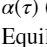


%% 4. Figures 

% --- Figure 1: Pitch (Alpha) ---
figure(1)
plot(tau, rad2deg(alpha_t), 'b', 'LineWidth', 1.5);
hold on
yline(0, 'k--', 'LineWidth', 1);
legend('$\alpha(\tau)$ (Pitch)', 'Equilibrium', 'Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$ (Dimensionless Time)','interpreter','latex')
ylabel('Pitch Angle $\alpha$ (deg)','interpreter','latex')
title(['Aeroelastic Response at U = ' num2str(U_inf) ' m/s'],'interpreter','latex');
xlim([0 tau_max])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

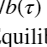


% --- Figure 2: Plunge (h/b) ---
figure(2)
plot(tau, h_b_t, 'r', 'LineWidth', 1.5);
hold on
yline(0, 'k--', 'LineWidth', 1);
legend('$h/b(\tau)$ (Plunge)', 'Equilibrium', 'Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$ (Dimensionless Time)','interpreter','latex')
ylabel('Plunge Displacement $h/b$','interpreter','latex')
title(['Aeroelastic Response at U = ' num2str(U_inf) ' m/s'],'interpreter','latex');
xlim([0 tau_max])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

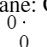


% --- Figure 3: Phase plane (Alpha vs h/b) 
figure(3)
plot(h_b_t, rad2deg(alpha_t), 'k', 'LineWidth', 1);
xlabel('$h/b$','interpreter','latex')
ylabel('$\alpha$ (deg)','interpreter','latex')
title('Phase Plane: Coupling','interpreter','latex');
grid on; box on;
set(gcf, 'Units', 'inches', 'Position', [0, 0, 5, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

## Unsteady Drag Aeroelastic Instabilities

Now that the classic 2 DoF system has been studied using state-space representation, the next step is to include the effect of the unsteady drag in the aeroelastic behavior of the system. To do this, new aspects need to be taken into account. The first and most evident, is that the drag does not contribute to the vertical force related to the plunge degree of freedom nor to the moment related to the pitch degree of freedom. Thus, the way to incorporate the effect of the unsteady drag, is through the surge (horizontal degree of freedom). 

This can be done in two different ways. The first, is by using the freestream velocity as a new state which can change in time due to the effect of the drag. The second, is by permit the motion of the airfoil in the horizontal plane, and applying and horizontal stiffness (as a linear spring).

Here on, the first approach is analyzed. To do that, a new state is introduced to the system: The freestream velocity, now on called $U\ldotp$ Note that the equations are going to be rearranged, in order to be developed in the physical time instead of the non dimensional time. This is done to avoid new terms that would appear when applying the non dimensional time derivatives due to the chain derivation rule, as now $U$ is not a constant, i.e. $U = U(t)$. This means that the previously used relation $\frac{d^2\xi}{dt^2} = \left(\frac{U}{b}\right)^2\frac{d^2\xi}{d\tau^2} $ is no longer valid, as now the derivatives of the freestream velocity with respect to time, need to be also considered, which would lead to new terms that complicate the formulation of the system's equations.

Moreover, the equations of lift and moment need to be revisited, as Theodorsen's model, which was the fundamental theory used to compute the aerodynamic loads in the previous cases, is now incomplete, as it does not take into account that changes in the freestream velocity (i.e. $\dot U$), produce new circulatory and non circulatory terms. These terms can be known thanks to the work of J.M Greenberg's (NACA Report No. 1326), which improves Theodorsen's theory by adding these terms due to the flow horizontal acceleration. 

The non dimensional lift and moment, with this new correction, reads as follows:


$$    \frac{{Q}_h(k)}{q_\infty b} = -2\pi\left[\frac{b}{U_}\dot{\alpha} + \left(\frac{b}{U_}\right)^2\left(\frac{\ddot{h}}{b} - a\ddot\alpha\right) + \frac{b \dot U}{U^2}\alpha \right]-4\pi C(k)\left\{\alpha+\frac{b}{U}\left[\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right] + \frac{b \dot U}{U^2}\alpha\right\}$$



$$\frac{{Q}_\alpha(k)}{q_\infty b^2} = -2\pi\left\{\frac{b}{U}\left(\frac{1}{2}-a\right)\dot{\alpha} + \left(\frac{b}{U}\right)^2\left[-a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right] - a \frac{b \dot U}{U^2}\alpha\right\} + 4\pi \left(\frac{1}{2}+a\right) C(k)\left\{\alpha+\frac{b}{U}\left[\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right] + \frac{b \dot U}{U^2}\alpha\right\}$$


where the terms proportional to $\dot U$are the ones added from Greenberg's theory.

The process followed to obtain the complete system's lift and moment equations is the same as the previous one (RT.Jones approximation of Wagner's function is used along with the convolution integral to obtain the aerodynamic loads for arbitrary motion in time domain, and then, the augmented aerodynamic states are defined to transform the convolution integrals in a system of time ODE's for these introduced states). 

Note that as always, the non circulatory contributions stay the same, as they are directly given for the time derivatives of the degrees of freedom of the system in the time domain. Nevertheless, the circulatory parts have now a new contribution which changes the definition of the augmented aerodynamic states, as now the circulatory part is no longer $\frac{{Q}^C_h(k)}{q_\infty b}  = - 4\pi C(k)\hat w_{3/4}$, as the new term needs to be considered: $\frac{{Q}^C_h(k)}{q_\infty b}  = - 4\pi C(k)\left(\hat w_{3/4} + \frac{b \dot U}{U^2}\alpha \right)$. 

Thus, defining a new aerodynamic variable as $\hat W = \hat w_{3/4} + \frac{b \dot U}{U^2}\alpha$:


$$\hat W(t) = \alpha + \left(\frac{b}{U}\right) \frac{\dot h}{b} + \left(\frac{1}{2}-a\right)\left(\frac{b}{U}\right) \dot \alpha+ \frac{b \dot U}{U^2}\alpha$$


The circulatory contributions can be determined as:


$$\frac{{Q}^C_h(t)}{q_\infty b}   = - 4\pi\left(\hat W(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat W(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right)$$



$$\frac{{Q}^C_\alpha(t)}{q_\infty b}   =  4\pi \left(\frac{1}{2}+a\right)  \left(\hat W(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat W(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right)$$


Hence, the new definition of the augmented aerodynamic states would be:


$$\dot x_i(t) = \frac{U}{b} \left(\hat W(t) -\epsilon_ix_i(t) \right) =  \frac{U}{b} \left\{\alpha+\frac{b}{U}\left[\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right] + \frac{b \dot U}{U^2}\alpha  - \epsilon_ix_i(t) \right\}$$


Notice that the term $ \frac{U}{b}$ is new, as in the last formulation of the aerodynamic states, the time derivative was taken with respect to non dimensional time. In order to correct it for real time, this coefficient needs to be included.

Applying the process explained in the unsteady aerodynamic script, the previous expressions of the the convolution integrals lead to:


$$\frac{{Q}_h(t)}{q_\infty b} = -2\pi\left[\frac{b}{U_}\dot{\alpha} + \left(\frac{b}{U_}\right)^2\left(\frac{\ddot{h}}{b} - a\ddot\alpha\right) + \frac{b \dot U}{U^2}\alpha \right]-4\pi \left[\hat W(t) \Phi_0+ \epsilon_1 \psi_1 x_1(t) + \epsilon_2 \psi_2 x_2(t) \right]$$



$$\frac{{Q}_\alpha(t)}{q_\infty b^2} = -2\pi\left\{\frac{b}{U}\left(\frac{1}{2}-a\right)\dot{\alpha} + \left(\frac{b}{U}\right)^2\left[-a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right] - a \frac{b \dot U}{U^2}\alpha\right\} + 4\pi \left(\frac{1}{2}+a\right) \left[\hat W(t) \Phi_0+ \epsilon_1 \psi_1 x_1(t) + \epsilon_2 \psi_2 x_2(t) \right]$$


Note that $x_1(\tau)$ and $x_2(\tau)$ are the two augmented aerodynamic states (one for each exponential term of the Wagner's function approximation given by R.T.Jones, as previously used).

In order to compute the new equations for the whole aeroelastic system, the same notation is used, but now including the freestream velocity as a state of the aeroelastic system:


$$\left\{\frac{h}{b}, \alpha , \frac{\dot h}{b}, \dot \alpha, x_1^{aero}, x_2^{aero}, U\right\}^T = \left\{x_1, x_2, x_3, x_4, x_5, x_6, x_7 \right\} ^T$$


The new system consists in a 7 equations with 7 unknowns system. As it can be seen if the expressions of lift and moment are observed, now the system becomes clearly non linear, as the horizontal velocity $U$is a state which appears squared in some of the terms. Furthermore, it is going to be also analyzed, that the last equation of the system (equation 7), also includes nonlinearities in the rest of the states, not only in $U$.

The first two equations of the new system stay the same as for the original:


$$\dot x_1 = x_3$$



$$\dot x_2 = x_4
$$


However, the lift and moment equations are now different, due to the new contributions originated by the $\dot U$terms, as well as the nonlinearities produced by the velocity sate $U$. Also, in needs to be taken into account that the aeroelastic equations are non dimensionalize the same way than the original system. But now, the dynamic pressure is a function of the state $U$:


$$\frac{Q_{aero}}{Mb} = \frac{Q_{aero}}{q_\infty b} \cdot \frac{1}{2\pi \mu}  \cdot \left( \frac{U}{b} \right)^2 = \frac{Q_{aero}}{q_\infty b} \cdot \frac{1}{2\pi \mu}  \cdot \left( \frac{x_7}{b} \right)^2$$


Thus, the previous expression for de unsteady aerodynamic forces $\frac{{Q}_h(t)}{q_\infty b}  $ and $\frac{{Q}_m(t)}{q_\infty b}  $ need to be multiplied by the coefficient $\frac{1}{2\pi \mu}  \cdot \left( \frac{x_7}{b} \right)^2$.

Hence, both lift and moment equations can be now formulated as:


$$\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right]\left\{\matrix{ \dot x_3 \cr \dot x_4}\right\}  + \omega_\alpha^2 \left[\matrix{\left(\frac{\omega_h}{\omega_\alpha}\right)^2 & 0 \cr  0 & r_\alpha^2}\right] \left\{\matrix{ x_1 \cr x_2}\right\}  =  \left\{\matrix{ \frac{Q_h(t)}{Mb} \cr \frac{Q_\alpha(t)}{Mb}}\right\}  $$



$$\frac{Q_h(t)}{Mb} = -\frac{1}{\mu} \left[ \dot{x}_3 - a\dot{x}_4 + \frac{x_7}{b}x_4 + \frac{\dot{x}_7}{b}x_2 \right] - \frac{2}{\mu} \left( \frac{x_7}{b} \right)^2 \left[ \Phi_0 \hat W(t) + \epsilon_1 \psi_1 x_5 + \epsilon_2 \psi_2 x_6 \right]$$



$$\frac{Q_\alpha(t)}{Mb^2} = -\frac{1}{\mu} \left[ -a\dot{x}_3 + \left(\frac{1}{8}+a^2\right)\dot{x}_4 + \left(\frac{1}{2}-a\right)\frac{x_7}{b}x_4 - a\frac{\dot{x}_7}{b}x_2 \right] + \frac{2}{\mu}\left(\frac{1}{2}+a\right) \left( \frac{x_7}{b} \right)^2 \left[ \Phi_0 \hat W(t) + \epsilon_1 \psi_1 x_5 + \epsilon_2 \psi_2 x_6 \right]$$


with:


$$\hat W(t) = x_2 + \frac{b}{x_7}x_3 + \left(\frac{1}{2}-a\right)\frac{b}{x_7}x_4 + \frac{b \dot{x}_7}{x_7^2}x_2$$


For the equations 5 and 6 which come from the definition of the augmented aerodynamic states, we now have:


$$\dot{x}_5 = \frac{x_7}{b} x_2 + x_3 + \left(\frac{1}{2} - a\right)x_4 + \frac{\dot{x}_7}{x_7}x_2 - \frac{\varepsilon_1 x_7}{b} x_5$$



$$\dot{x}_6 = \frac{x_7}{b} x_2 + x_3 + \left(\frac{1}{2} - a\right)x_4 + \frac{\dot{x}_7}{x_7}x_2 - \frac{\varepsilon_2 x_7}{b} x_6$$


Lastly, we need to introduce the new equations that closes the system and determines how the unsteady drag is coupled with the aeroelastic system. This way, the unsteady drag allows the system to change its horizontal speed $U = x_7$, and therefore, the system can damp or diverge depending in the behavior. If the horizontal speeds increases, the unsteady aerodynamic loads push the aeroelastic system to harder instabilities that would lead to the flutter of the wing. However, if the unsteady drag decelerates the system horizontal speed, the aeroelastic instability can be damped out due to the decreasing effect of the aerodynamic loads due to the decrease of the dynamic pressure. This effect is greatly affected by the non linear behavior of this new system, which transforms a classical linear flutter problem, in a limit cycle oscillation behavior (LCO's).

The equation is based on the horizontal rigid body motion of the dynamics of the system, idea that is introduced in Patil's paper:


$$m \dot U = T - \frac{1}{2} \rho_\infty U^2 b \cdot C_{d_{total}}$$


The mass of the system is directly connected with the non dimensional mass parameter used previously in lift and moment equations, as $\mu = \frac{m}{\pi\rho_\infty b^2$.

$T$ is the constant thrust parameter, which can be set to zero for modeling a glider or a simple flying wing behavior. The total drag coefficient can be split in two contributions. The parasite steady drag due to friction (assuming that the boundary layer friction remains constant during the motion of the wing), and the previously studied unsteady potential drag:


$$C_{d,total}(t) = C_{d0} + C_{d}(t)$$


Recall that for constant freestream velocity flows, we obtained from Garrick's theory, a time domain state representation of the unsteady potential drag:


$$C_d(t) = \alpha C_l(t) - \pi \left\{2\left[ \hat w_{3/4}(t)\Phi_0 + \sum_{i =1}^{n}\epsilon_i \psi_i x_i(t) \right] - \dot \alpha \right\}^2$$


To account for the new contributions from Greenberg's theory for varying velocity flows, and using the notation for the states of the aeroelastic system, the unsteady drag can be written as:


$$C_d(t) = x_2C_l(t) - \pi \left\{2\left[ \hat W(t)\Phi_0 + \epsilon_1 \psi_1 x_5 +  \epsilon_2 \psi_2 x_6 \right] - x_4 \right\}^2$$


where


$$C_l(t) = 2\pi \left[ \frac{b}{x_7} x_4 + \left(\frac{b}{x_7}\right)^2 \left( \dot{x}_3 - a \dot{x}_4 \right) + \frac{b \dot{x}_7}{x_7^2} x_2 \right] + 4\pi \left[ \Phi_0 \hat W(t) + \varepsilon_1 \psi_1 x_5 + \varepsilon_2 \psi_2 x_6 \right]$$


and 


$$\hat W(t) = x_2 + \frac{b}{x_7}x_3 + \left(\frac{1}{2}-a\right)\frac{b}{x_7}x_4 + \frac{b \dot{x}_7}{x_7^2}x_2$$


Note that the Greenberg's therms, are included inside the new definition of the lift coefficient $C_l(t)$ and the aerodynamic downwash$\hat W(t)$. 

Hence, the last equation can be rewritten as:


$$m \dot x_7 = T - \frac{1}{2} \rho_\infty x_7^2 b \cdot \left( C_{d0} + C_d(t) \right)$$


As it can be seen, this last equation is the one that contains the largest nonlinearities, both due to the squared $x_7^2$ term, and due to the non linear definition of the unsteady potential drag given in Garrick's theory.